**Testul 1**

Problema 2

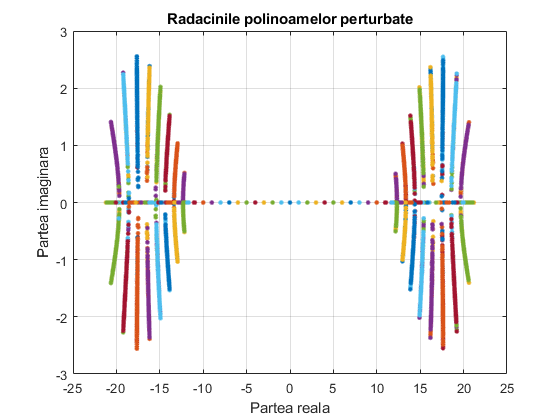

n = 20;

% Parametrii distributiei normale
ll = 0;
lr = 10^(-5);

% Matricea care va stoca toate radacinile
all_roots = complex([]);

% Coeficientii polinomului
coeffs = poly(-n:n);  % Create a polynomial with roots -n:n

% Numarul de repetari
m = 1000;

for i = 1:m
    % Generez perturbatii aleatoare cu distributia normala
    perturbations = ll + lr * randn(size(coeffs));
    
    % Coeficientul liber ramane neperturbat
    perturbations(end) = 0;

    % Adaug perturbatiile la coeficientii originali
    perturbed_coeffs = coeffs + perturbations;

    % Gasesc radacinile polinomului perturbat
    perturbed_roots = roots(perturbed_coeffs);

    % Adauga radacinile la matrice
    all_roots = [all_roots; transpose(perturbed_roots)];
end

% Reprezint grafic radacinile gasite
figure;
plot(real(all_roots), imag(all_roots), '.', 'MarkerSize', 10);
title('Radacinile polinoamelor perturbate');
xlabel('Partea reala');
ylabel('Partea imaginara');
grid on;